# Add Sensors to RoadRunner Scenario Using Simulink

Define sensor models in Simulink®, and add them to vehicle actors in a RoadRunner Scenario. Then, obtain ground truth measurements from RoadRunner Scenario, process them into detections in Simulink for visualization.

## Set Up RoadRunner Scenario — Simulink Interface

Configure your RoadRunner installation and project folder properties. Open the RoadRunner app.

rrInstallationPath = "C:\Program Files\RoadRunner R2023b\bin\win64";
rrProjectPath = "C:\Users\parks\OneDrive\Documents\MATLAB\Examples\R2023b\Add Sensors";

s = settings;
s.roadrunner.application.InstallationFolder.PersonalValue = rrInstallationPath;
rrApp = roadrunner(rrProjectPath);

To open the scenario this example uses, you must add these files from the example folder to your RoadRunner project folder:

- `straightCurvedFourLaneRoad.rrscene` — RoadRunner scene file that describes the four lane highway.

- `SensorDerectionSimulation.rrscenario` — RoadRunner scenario file that describes actors and their trajectories on the four lane highway scene.

- `SensorIntegration.rrbehavior.rrmeta` — Behavior file that associates the sensor detection processing and visualization behavior using Simulink, to the ego vehicle in the RoadRunner scenario. 

copyfile("straightCurvedFourLaneRoad.rrscene",fullfile(rrProjectPath,"Scenes/"));
copyfile("SensorDetectionSimulation.rrscenario",fullfile(rrProjectPath,"Scenarios/"))
copyfile("SensorIntegration.rrbehavior.rrmeta",fullfile(rrProjectPath,"Assets","Behaviors/"))

  Open the scenario and create a `ScenarioSimulation` object to connect Simulink with the RoadRunner Scenario.

openScenario(rrApp,"SensorDetectionSimulation")
rrSim = createSimulation(rrApp);

Connection status: 1
Connected to RoadRunner Scenario server on localhost:39726, with client id {ebd0e146-c2e6-486d-b4cf-f23d61e73681}


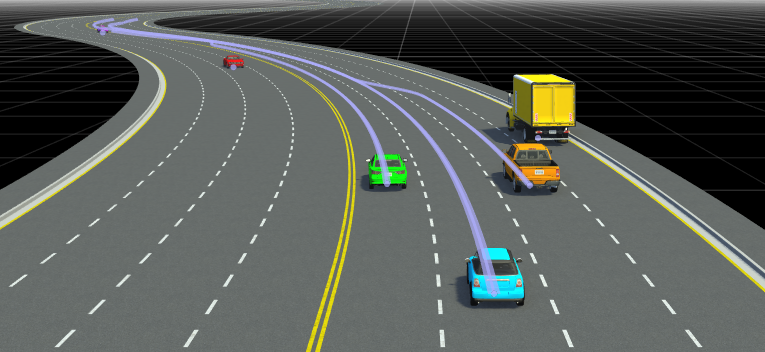

Specify the step size for the RoadRunner scenario simulation. The Simulink model also uses the same step size. Units are in seconds.

simStepSize = 0.1;
set(rrSim,"StepSize",simStepSize);

## Inspect Simulink Model and Simulate Scenario

The Simulink model `rrScenarioSimWithSensors` configures sensor models for the vision, radar and lidar sensors using the [Vision Detection Generator](docid:driving_ref#mw_2fa86dfd-52db-4f59-8781-7d954ae3e8dc), [Driving Radar Data Generator](docid:driving_ref#mw_535e4736-f89b-4dc7-a609-b8c323c4ce32) and [Lidar Point Cloud Generator](docid:driving_ref#mw_b87c4ea6-1e17-45b6-8b0c-62226f5a1b28) blocks respectively. The model reads ground truth data from the scenario and processes that into detections and visualizes the detections. It also reads the path defined for the ego vehicle from the RoadRunner Scenario, implements the path follower logic and controls the ego vehicle motion along the path. 

Load the bus definitions and open the model. Note that the lidar sensor model block does not require any ground-truth target pose inputs.

load("busDefinitionsForRRSim.mat")
modelName = 'rrScenarioSimWithSensors';
open_system(modelName)

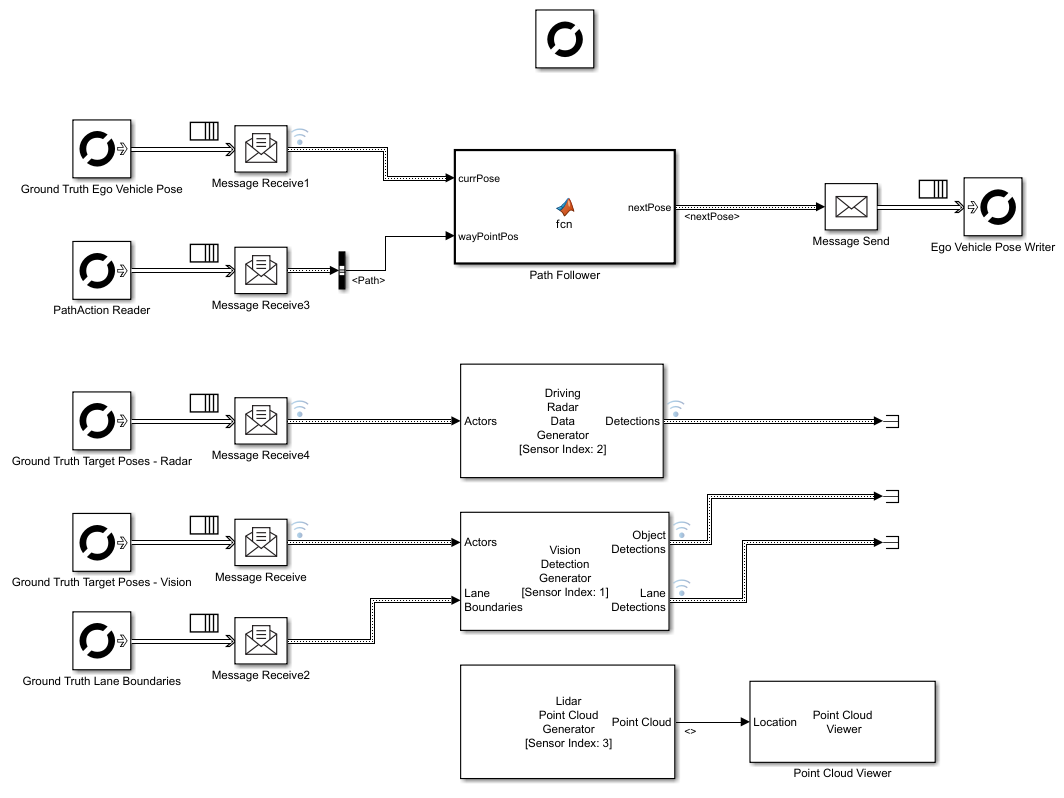

Create a `SensorSimulation` object. Specify the block paths for the radar, vision and lidar sensors in the model.

sensorSim = get(rrSim,"SensorSimulation");
visionSensorBlkPath = [modelName,'/Vision Detection Generator'];
radarSensorBlkPath = [modelName,'/Driving Radar Data Generator'];
lidarSensorBlkPath = [modelName,'/Lidar Point Cloud Generator'];

Add the three sensors to the ego vehicle using the `addSensors` function. 

egoVehicleId = 1;
addSensors(sensorSim,{visionSensorBlkPath,radarSensorBlkPath,lidarSensorBlkPath},egoVehicleId);

To visualize the scenario and sensor detections, use the Bird'sEye Scope app. On the Simulink toolstrip, under **Review Results**, click **Bird's-Eye Scope**. Then in the scope, click **Find Signals **to establish connection with the RoadRunner scenario and populate the signals to visualize.

Start the scenario Simulation. The model visualizes the 3D point cloud using the Point Cloud Viewer block during the simulation. In Bird's-Eye Scope, you can visualize the 2D point cloud, object detections and lane detections alongside ground truth values.

%set(rrSim,"SimulationCommand","Start")

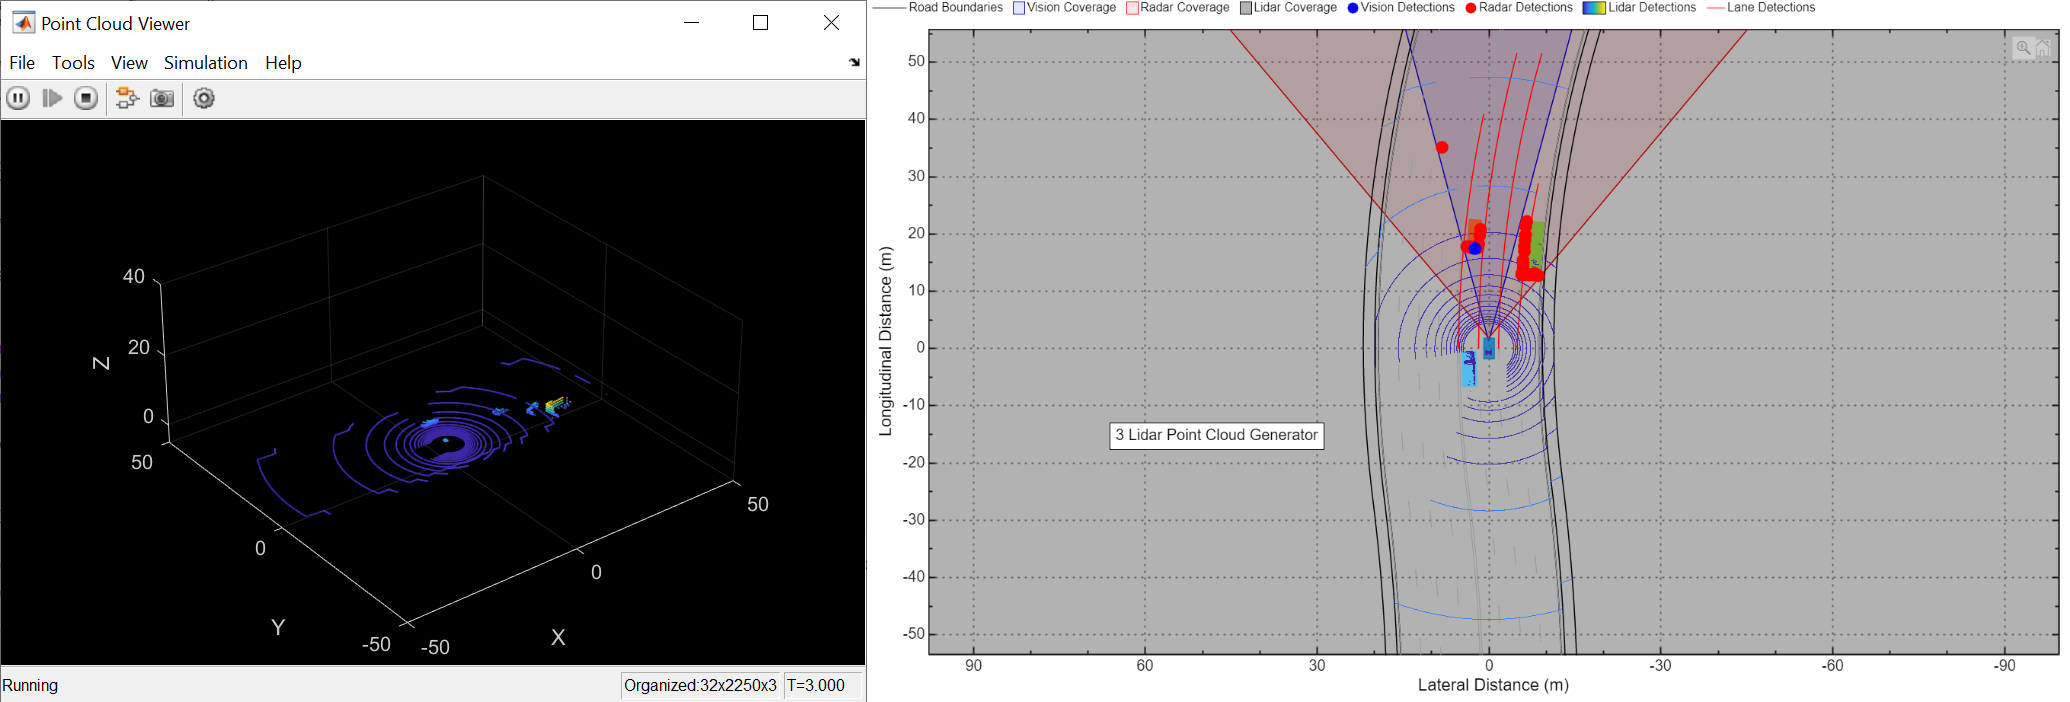

*Copyright 2022 The MathWorks, Inc.*